close all
clearvars

Загрузка данных

load data_after.txt
load data_before.txt
load calibration_1.txt
load calibration_2.txt
load calibration_3.txt
load calibration_4.txt
load calibration_5.txt
load calibration_6.txt

Обработка данных

adc40 = calibration_1

adc40 =     48
    48
    48
    48
    48
    48
    48
    48
    48
    48


adc60 = calibration_2

adc60 =     67
    67
    67
    67
    67
    67
    67
    67
    68
    68


adc80 = calibration_3

adc80 =     89
    89
    89
    89
    89
    90
    89
    89
    89
    90


adc100 = calibration_4

adc100 =    107
   106
   106
   106
   106
   106
   106
   106
   107
   106


adc120 = calibration_5

adc120 =    128
   126
   126
   126
   126
   126
   126
   126
   125
   126


adc140 = calibration_6

adc140 =    146
   146
   146
   146
   146
   146
   145
   146
   146
   146



torr40 = ones(length(adc40), 1) * 40

torr40 =     40
    40
    40
    40
    40
    40
    40
    40
    40
    40


torr60 = ones(length(adc60), 1) * 60

torr60 =     60
    60
    60
    60
    60
    60
    60
    60
    60
    60


torr80 = ones(length(adc80), 1) * 80

torr80 =     80
    80
    80
    80
    80
    80
    80
    80
    80
    80


torr100 = ones(length(adc100), 1) * 100

torr100 =    100
   100
   100
   100
   100
   100
   100
   100
   100
   100


torr120 = ones(length(adc120), 1) * 120

torr120 =    120
   120
   120
   120
   120
   120
   120
   120
   120
   120


torr140 = ones(length(adc140), 1) * 140

torr140 =    140
   140
   140
   140
   140
   140
   140
   140
   140
   140



cAdc = [adc40; adc60; adc80; adc100; adc120; adc140]

cAdc =     48
    48
    48
    48
    48
    48
    48
    48
    48
    48


cTorr = [torr40; torr60; torr80; torr100; torr120; torr140]

cTorr =     40
    40
    40
    40
    40
    40
    40
    40
    40
    40


c = polyfit(cAdc, cTorr, 1)

c =     1.0252   -9.6205


cFigure = figure('Name', 'Калибровка', 'NumberTitle',"off")

cFigure =   Figure (1: Калибровка) with properties:

      Number: 1
        Name: 'Калибровка'
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


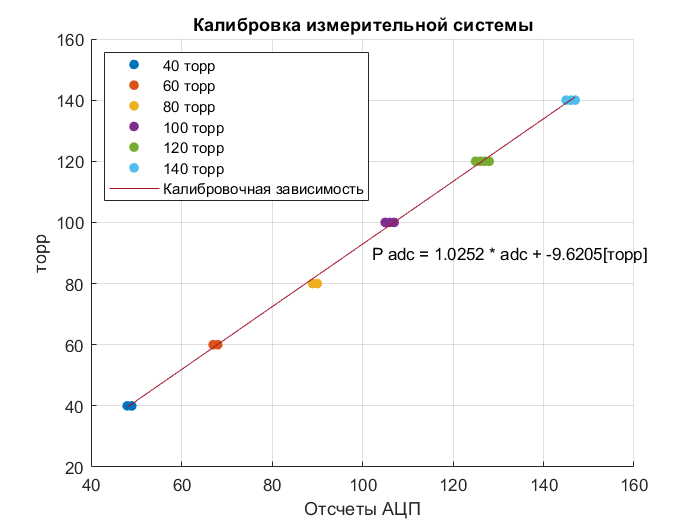

hold all

plot(adc40, torr40, '.', 'MarkerSize', 20)
plot(adc60, torr60, '.', 'MarkerSize', 20)
plot(adc80, torr80, '.', 'MarkerSize', 20)
plot(adc100, torr100, '.', 'MarkerSize', 20)
plot(adc120, torr120, '.', 'MarkerSize', 20)
plot(adc140, torr140, '.', 'MarkerSize', 20)

plot(cAdc, polyval(c, cAdc))

legend('40 торр', '60 торр', '80 торр', '100 торр', '120 торр', '140 торр', 'Калибровочная зависимость', 'Location',"northwest")

grid on
xlabel('Отсчеты АЦП')
ylabel('торр')
title('Калибровка измерительной системы')
text(mean(cAdc) * 1.05, mean(cTorr), ['P adc = ', num2str(c(1)), ' * adc + ', num2str(c(2)), '[торр]'])
saveas(cFigure, 'Калибровка.png')

Визуализация измерений

dt = 0.01

dt = 0.0100

adcBefore = data_before

adcBefore =    165
   165
   164
   165
   165
   164
   165
   164
   164
   164


tBefore = linspace(0, length(adcBefore) * dt, length(adcBefore))

tBefore =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1601    0.1701    0.1801    0.1901    0.2001    0.2101    0.2201    0.2301    0.2401    0.2501    0.2601    0.2701    0.2801    0.2901    0.3001    0.3101    0.3201    0.3301    0.3401    0.3501    0.3601    0.3701    0.3801    0.3901    0.4001    0.4101    0.4201    0.4301    0.4401    0.4501    0.4602    0.4702    0.4802    0.4902


pBefore = polyval(c, adcBefore)

pBefore =   159.5321
  159.5321
  158.5069
  159.5321
  159.5321
  158.5069
  159.5321
  158.5069
  158.5069
  158.5069



adcAfter = data_after

adcAfter =    159
   159
   159
   159
   159
   159
   159
   159
   159
   159


tAfter = linspace(0, length(adcAfter) * dt, length(adcAfter))

tAfter =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1601    0.1701    0.1801    0.1901    0.2001    0.2101    0.2201    0.2301    0.2401    0.2501    0.2601    0.2701    0.2801    0.2901    0.3001    0.3101    0.3201    0.3301    0.3401    0.3501    0.3601    0.3701    0.3801    0.3901    0.4001    0.4101    0.4201    0.4301    0.4401    0.4501    0.4602    0.4702    0.4802    0.4902


pAfter = polyval(c, adcAfter)

pAfter =   153.3811
  153.3811
  153.3811
  153.3811
  153.3811
  153.3811
  153.3811
  153.3811
  153.3811
  153.3811



pFigure = figure("Name", 'Графики давления', "NumberTitle","off")

pFigure =   Figure (2: Графики давления) with properties:

      Number: 2
        Name: 'Графики давления'
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


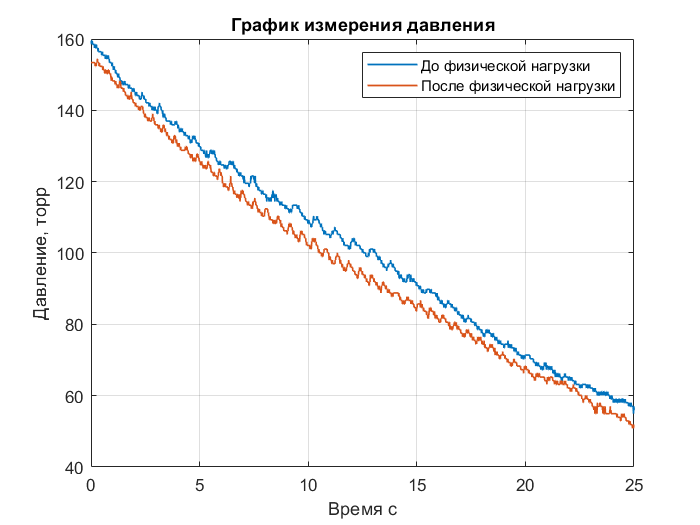


plot(tBefore, pBefore, tAfter, pAfter, 'LineWidth', 1)
legend('До физической нагрузки', 'После физической нагрузки')

grid on
xlim([0, 25])

xlabel('Время с')
ylabel('Давление, торр')
title('График измерения давления')

saveas(pFigure, 'Давление.png')

Обработка

cBefore = polyfit(tBefore, pBefore, 7)

cBefore =     0.0000   -0.0000    0.0006   -0.0120    0.1118   -0.2505   -6.1340  158.5914


cAfter = polyfit(tAfter, pAfter, 5)

cAfter =     0.0000   -0.0001   -0.0028    0.2070   -6.9104  155.1981



pulseBefore = pBefore - polyval(cBefore, tBefore)'

pulseBefore =     0.9407
    1.0021
    0.0384
    1.1250
    1.1866
    0.2230
    1.3098
    0.3463
    0.4080
    0.4698


pulseAfter = pAfter - polyval(cAfter, tAfter)'

pulseAfter =    -1.8169
   -1.7478
   -1.6788
   -1.6097
   -1.5408
   -1.4718
   -1.4029
   -1.3341
   -1.2653
   -1.1965



pulseFigure = figure("Name", 'График пульса', 'NumberTitle',"off")

pulseFigure =   Figure (3: График пульса) with properties:

      Number: 3
        Name: 'График пульса'
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


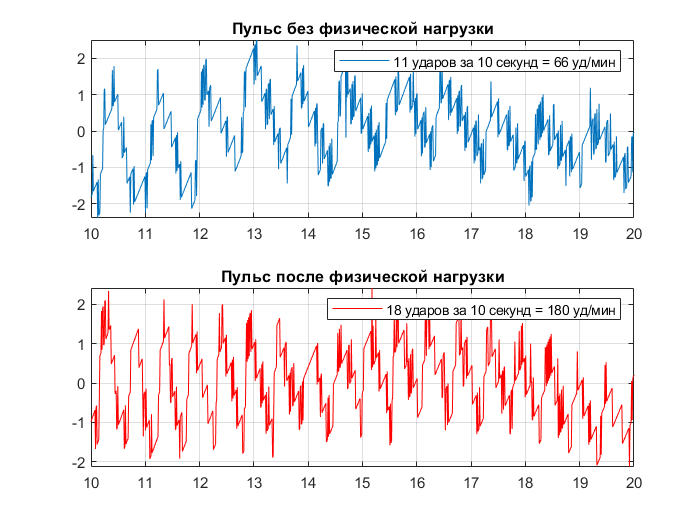


subplot(2, 1, 1)
plot(tBefore, pulseBefore)
legend('11 ударов за 10 секунд = 66 уд/мин')
grid on
xlim([10, 20])
title('Пульс без физической нагрузки')

subplot(2, 1, 2)
plot(tAfter, pulseAfter, 'r')
legend('18 ударов за 10 секунд = 180 уд/мин')
title('Пульс после физической нагрузки')
grid on
xlim([10, 20])

saveas(pulseFigure, 'Пульс.png')